# Machine Learning with MATLAB - Part 3

Digital Twin & Automation

# K-Nearest Neighbors

## Example1: Classification Using Nearest Neighbors

**Distance Metrics**

Use [`pdist2`](https://kr.mathworks.com/help/stats/pdist2.html) to find the distance between a set of data and query points.

- Euclidean distance

- Standardized Euclidean distance

- Mahalanobis distance

- Cosine distance

***k*****-Nearest Neighbor Search and Radius Search**

- **Exhaustive Search(default)**

- **Kd-Tree (feature <10)**

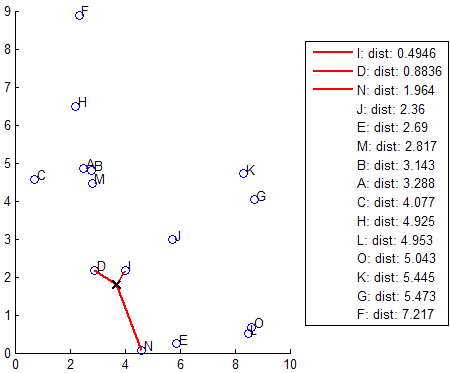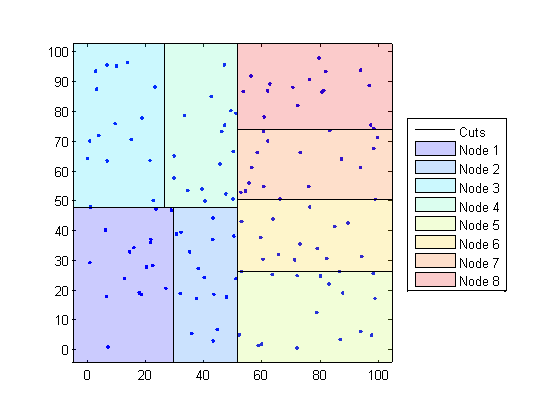

## Example 1 : K-NN using Custom Distance Metric

Randomly generate normally distributed data into two matrices. The number of rows can vary, but the number of columns must be equal. This example uses 2-D data for plotting.

clear

rng(1) % For reproducibility

% Input Data
X = randn(50,2);

% Query
Y = randn(4,2);

h = zeros(3,1);
figure
h(1) = plot(X(:,1),X(:,2),'bx');
hold on
h(2) = plot(Y(:,1),Y(:,2),'rs','MarkerSize',10);
title('Heterogeneous Data')

**Mahalanobis distance**

Find the indices of the three nearest observations in `X` to each observation in `Y`.

k = 3;

[Idx, D] = knnsearch(X,Y,'Distance','mahalanobis','k',k);

`idx` and `D` are 4-by-3 matrices.

- `idx(j,1)` is the row index of the closest observation in `X` to observation *j* of `Y`, and `D(j,1)` is their distance.

- `idx(j,2)` is the row index of the next closest observation in `X` to observation *j* of `Y`, and `D(j,2)` is their distance.

- And so on.

Identify the nearest observations in the plot.

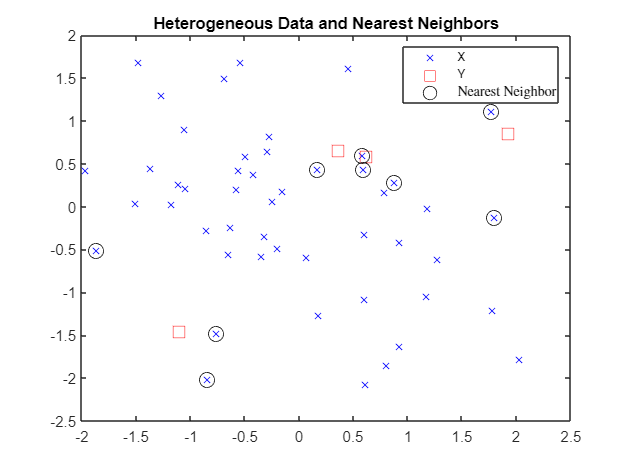

for j = 1:k

    h(3) = plot(X(Idx(:,j),1),X(Idx(:,j),2),'ko','MarkerSize',10);
end 

legend(h,{'\texttt{X}','\texttt{Y}','Nearest Neighbor'},'Interpreter','latex')
title('Heterogeneous Data and Nearest Neighbors')
hold off

# Exercise  

## Exercise 1: K-NN Classification with CWRU

### Dataset :  CWRU dataset features

- Given dataset contains many features extracted from CWRU dataset

- We will select 2~3 features for exercise

- Normal,  Outer and Inner Race Fault

clear

%% Train
load("../3_MachingLearning/CWRU_Datas/example_train.mat");
feature1 = "sv";                % skewness value of time data
feature2 = "ipf";               % impulse factor
X(:, 1) = table2array(glob_all_train(:, feature1));
X(:, 2) = table2array(glob_all_train(:, feature2));
Y = class_cwru_train;       % fault class
N = size(X,1);
tbl=table(X(:, 1),X(:, 2),Y);

%% Test
load("../3_MachingLearning/CWRU_Datas/example_test.mat");
Xtest(:, 1) = table2array(glob_all_test(:, feature1));
Xtest(:, 2) = table2array(glob_all_test(:, feature2));
Ytest = class_cwru_test;                                 
Ntest=size(Xtest,1);
tblTest=table(Xtest(:, 1),Xtest(:, 2),Ytest);

#### Plot Test Data

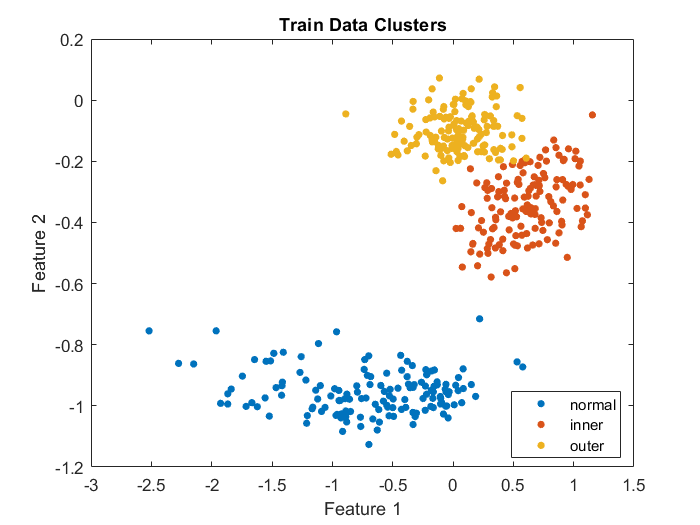

figure
gscatter(X(:,1),X(:,2),Y)
title('Train Data Clusters')
xlabel('Feature 1')
ylabel('Feature 2')

#### KNN Train

Construct the classifier using `fitcknn`.

rng(10); % For reproducibility

k = 3;
Mdl = fitcknn(X, Y,'NumNeighbors',4,'Standardize',1)

Mdl =   ClassificationKNN
             ResponseName: 'Y'
    CategoricalPredictors: []
               ClassNames: {'inner'  'normal'  'outer'}
           ScoreTransform: 'none'
          NumObservations: 432
                 Distance: 'euclidean'
             NumNeighbors: 4


  Properties, Methods


#### Training loss (all train set)

Examine the resubstitution loss, which, by default, is the fraction of misclassifications from the predictions of `Mdl`. (For nondefault cost, weights, or priors, see [loss](docid:stats_ug.bs85nh7).).

KnnResubErr = resubLoss(Mdl)

KnnResubErr = 0.0069

The classifier predicts incorrectly for 4% of the training data.

#### Cross-validation (k-fold)

Construct a cross-validated classifier from the model.

Examine the cross-validation loss, which is the average loss of each cross-validation model when predicting on data that is not used for training.

rng(0)
cv = cvpartition(Y,'KFold',10) 

cv = K-fold cross validation partition
   NumObservations: 432
       NumTestSets: 10
         TrainSize: 389  388  388  389  389  389  389  389  389  389
          TestSize: 43  44  44  43  43  43  43  43  43  43

cvMdl = crossval(Mdl,'CVPartition',cv);

MdlCVErr = kfoldLoss(cvMdl)

MdlCVErr = 0.0116

The cross-validated classification accuracy resembles the resubstitution accuracy. 

Therefore, you can expect `Mdl` to misclassify approximately 4% of new data, assuming that the new data has about the same distribution as the training data.

#### Predict test data

Predict the classification of test data

testPred = predict(Mdl,Xtest)

testPred = 108×1 cell array
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}


**Calculate the loss  of Test**

Loss = loss(Mdl, Xtest, Ytest);

**Plot  Confusion matrix of Test data**

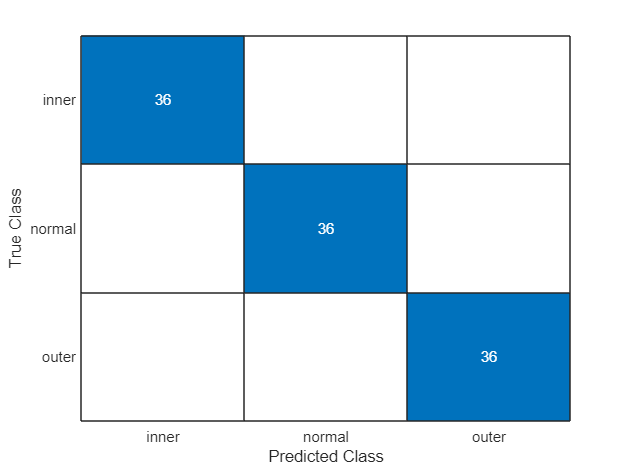

figure
resubCM = confusionchart(Ytest,testPred);

**Plot  Test Results and  Misclassified Test data**

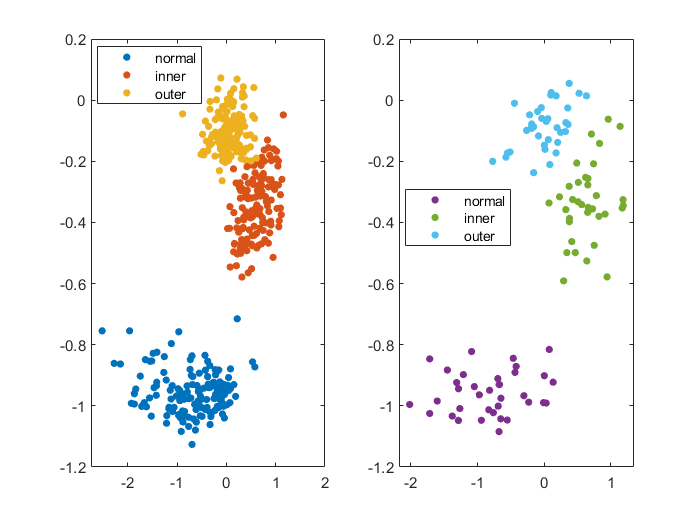

bad = ~strcmp(testPred,Ytest);

% Generate color values
color = lines(6);               

subplot(1,2,1)
gscatter(X(:,1),X(:,2),Y, color(1:3,:))

subplot(1,2,2)
gscatter(Xtest(:,1),Xtest(:,2),Ytest, color(4:6,:))

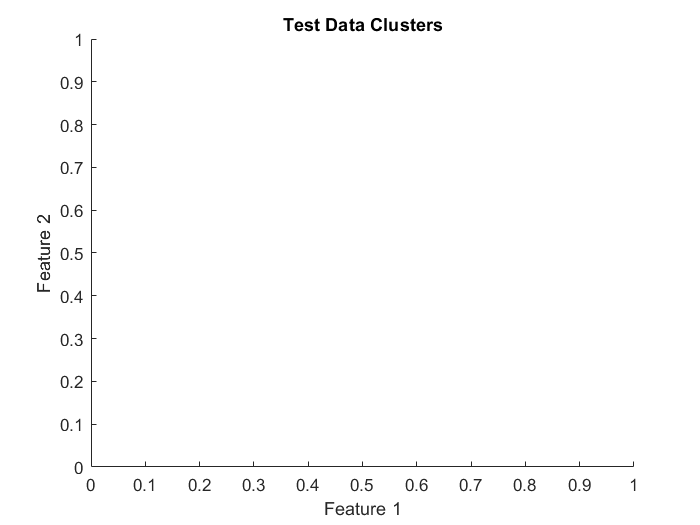

figure
plot(Xtest(bad,1), Xtest(bad,2), 'kx');
hold off;

title('Test Data Clusters')
xlabel('Feature 1')
ylabel('Feature 2')

#### Optimization of Fitted KNN

|=====================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   | NumNeighbors |     Distance |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |
|=====================================================================================================|
|    1 | Best   |      0.0625 |    0.047322 |      0.0625 |      0.0625 |          177 |  mahalanobis |
|    2 | Best   |   0.0092593 |    0.049308 |   0.0092593 |    0.012947 |            8 |  mahalanobis |
|    3 | Accept |     0.66667 |     0.04518 |   0.0092593 |    0.036145 |            2 |  correlation |
|    4 | Accept |     0.66667 |    0.064018 |   0.0092593 |    0.034601 |            1 |     spearman |
|    5 | Accept |    0.013889 |    0.052357 |   0.0092593 |    0.010155 |            1 |  mahalanobis |
|    6 | Accept |     0.66667 |    0.041115 |   0.0092593 |   0.

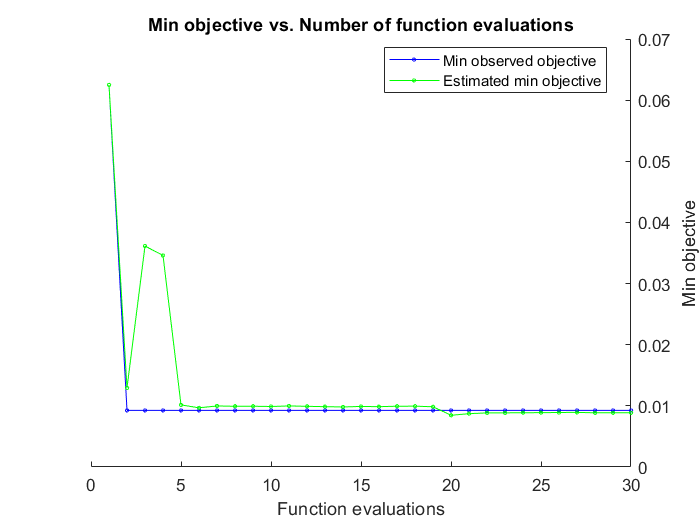

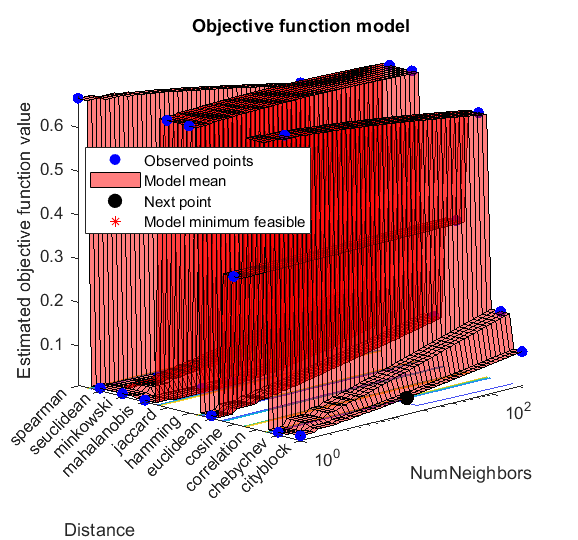


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 13.8232 seconds
Total objective function evaluation time: 1.426

Best observed feasible point:
    NumNeighbors     Distance  
    ____________    ___________

         8          mahalanobis

Observed objective function value = 0.0092593
Estimated objective function value = 0.011009
Function evaluation time = 0.049308

Best estimated feasible point (according to models):
    NumNeighbors     Distance  
    ____________    ___________

         4          mahalanobis

Estimated objective function value = 0.0088676
Estimated function evaluation time = 0.046885



Mdl =   ClassificationKNN
                         ResponseName: 'Y'
                CategoricalPredictors: []
                           ClassNames: {'inner'  'normal'  'outer'}
                       ScoreTransform: 'none'
                      NumObservations: 432
    HyperparameterOptimizationResults: [1×1 BayesianOptimization]
                             Distance: 'mahalanobis'
                         NumNeighbors: 4


  Properties, Methods


Mdl = fitcknn(X,Y,'OptimizeHyperparameters','auto',...
    'HyperparameterOptimizationOptions',...
    struct('AcquisitionFunctionName','expected-improvement-plus'))

## Exercise 2: CWRU 

Now, Use all 3 classes:  normal,  outer, inner.  Apply Multi_Class SVM 

**Features**

% Example
feature1 = "kv";
feature2 = "mf";
feature3 = "cf";

X(:, 1) = table2array(glob_all_train(:, feature1));       % Kurtosis value of time data
X(:, 2) = table2array(glob_all_train(:, feature2));       % Marginal-Factor
X(:, 3) = table2array(glob_all_train(:, feature3));       % Marginal-Factor

yCate = categorical(Y);
idx_inner = yCate == 'inner';
idx_outer = yCate == 'outer';
idx_normal = yCate == 'normal';

Xtest(:, 1) = table2array(glob_all_test(:, feature1));
Xtest(:, 2) = table2array(glob_all_test(:, feature2));
Xtest(:, 3) = table2array(glob_all_test(:, feature3));

Plot the test and train results in 3D graph.

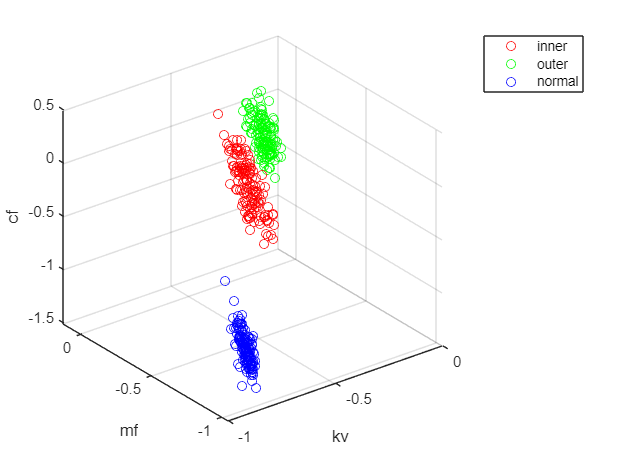

figure
plot3(X(idx_inner,1),X(idx_inner,2),X(idx_inner,3),'ro')
hold on
plot3(X(idx_outer,1),X(idx_outer,2),X(idx_outer,3),'go')
plot3(X(idx_normal,1),X(idx_normal,2),X(idx_normal,3),'bo') 
grid on
xlabel('kv')
ylabel('mf')
zlabel('cf')
legend('inner','outer','normal')
hold off

% K-Fold method
cv = cvpartition(Y,'KFold',10)  

cv = K-fold cross validation partition
   NumObservations: 432
       NumTestSets: 10
         TrainSize: 389  388  388  389  389  389  389  389  389  389
          TestSize: 43  44  44  43  43  43  43  43  43  43

## Training

Mdl = fitcknn(X, Y,'NumNeighbors',4,'Standardize',1)

Mdl =   ClassificationKNN
             ResponseName: 'Y'
    CategoricalPredictors: []
               ClassNames: {'inner'  'normal'  'outer'}
           ScoreTransform: 'none'
          NumObservations: 432
                 Distance: 'euclidean'
             NumNeighbors: 4


  Properties, Methods


KnnResubErr = resubLoss(Mdl)

KnnResubErr = 0

The classifier predicts incorrectly for 4% of the training data.

#### Cross-validation (k-fold)

Construct a cross-validated classifier from the model.

Examine the cross-validation loss, which is the average loss of each cross-validation model when predicting on data that is not used for training.

rng(0)
cv = cvpartition(Y,'KFold',10) 

cv = K-fold cross validation partition
   NumObservations: 432
       NumTestSets: 10
         TrainSize: 389  388  388  389  389  389  389  389  389  389
          TestSize: 43  44  44  43  43  43  43  43  43  43

cvMdl = crossval(Mdl,'CVPartition',cv);

MdlCVErr = kfoldLoss(cvMdl)

MdlCVErr = 0

testPred = predict(Mdl,Xtest)

testPred = 108×1 cell array
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}


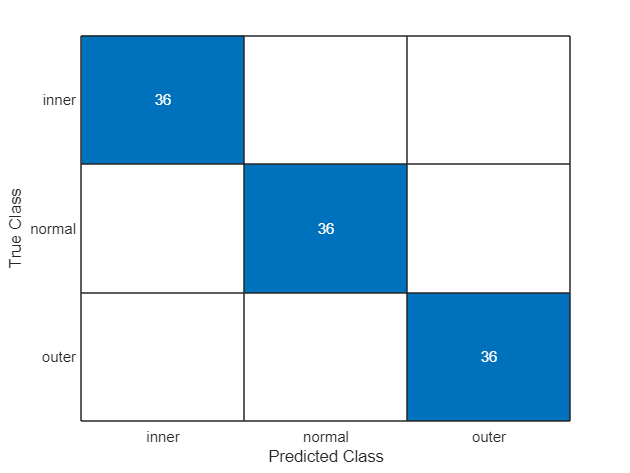

figure
resubCM = confusionchart(Ytest,testPred);

**Plot  Test Results and  Misclassified Test data**

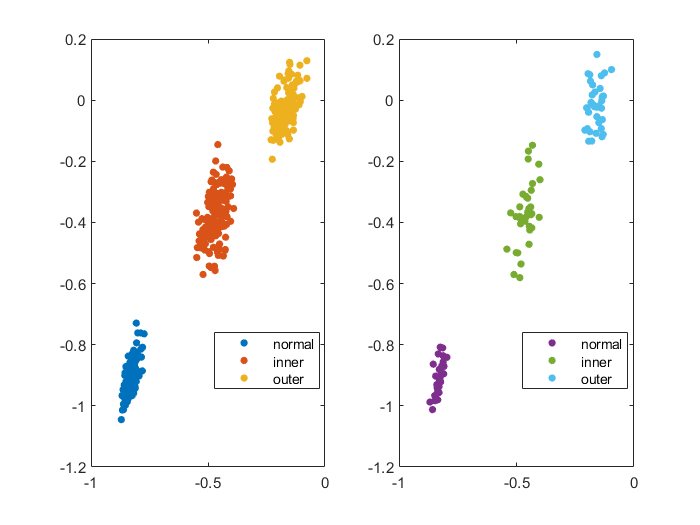

bad = ~strcmp(testPred,Ytest);

% Generate color values
color = lines(6);               

subplot(1,2,1)
gscatter(X(:,1),X(:,2),Y, color(1:3,:))

subplot(1,2,2)
gscatter(Xtest(:,1),Xtest(:,2),Ytest, color(4:6,:))

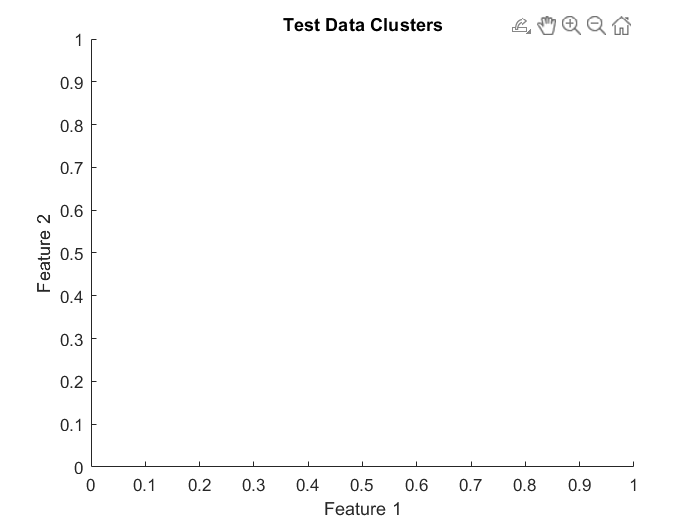

figure
plot(Xtest(bad,1), Xtest(bad,2), 'kx');
hold off;

title('Test Data Clusters')
xlabel('Feature 1')
ylabel('Feature 2')

## Exercise 3 

 Compare performance of KNN with other classification methods

- In KNN, k represents the number of nearest neighbors to consider when making a prediction for a new data point. In other words, when a new instance is to be classified, the k nearest neighbors (based on some distance metric such as Euclidean distance) from the training data are found.

- KNN, or k-Nearest Neighbors, is a non-parametric algorithm that makes predictions based on the k nearest neighbors in the training set. It has the advantage of being simple to implement and adaptable to different types of data. However, its performance can be sensitive to the choice of the k parameter and can be computationally expensive for large datasets.

- SVM, or Support Vector Machines, is a parametric algorithm that attempts to find a hyperplane that separates the different classes in the training data with a maximal margin. SVM can handle high-dimensional data well and is effective when the data is not linearly separable. However, SVM can be sensitive to the choice of kernel function and can be computationally expensive for large datasets.

- In terms of performance, the choice of algorithm depends on the specific problem and data at hand. In general, SVM and QDA are more suitable for datasets with a large number of features, while KNN is more suitable for datasets with a small number of features. SVM and QDA can achieve high accuracy for linearly separable data, while KNN can handle complex decision boundaries well. However, KNN can be sensitive to the choice of k parameter and can be computationally expensive for large datasets.